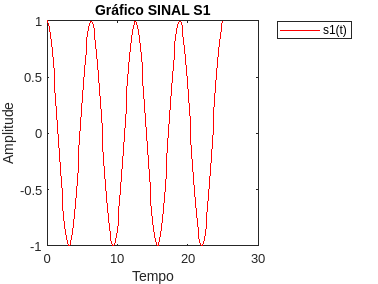

%serie 1 
t1 = linspace(0, 4*2*pi, 200);
s1 = cos(t1);
plot(t1, s1, 'r')
legend("s1(t)", 'Location', 'bestoutside')
xlabel('Tempo')
ylabel('Amplitude')
title('Gráfico SINAL S1')

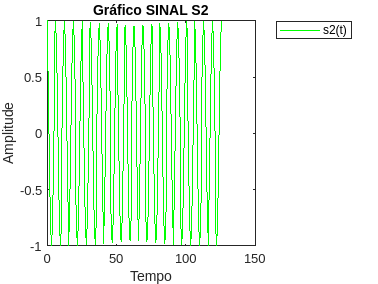


t2 = linspace(0, 20*2*pi, 200);
s2 = cos(t2);
plot(t2, s2, 'g')
legend("s2(t)", 'Location', 'bestoutside')
xlabel('Tempo')
ylabel('Amplitude')
title('Gráfico SINAL S2')

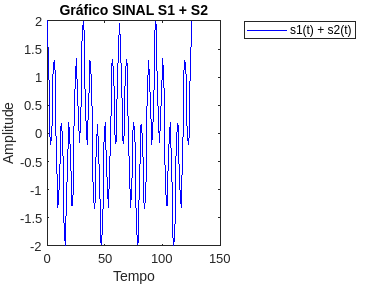


s3 = s1 + s2;
plot(t2, s3, 'b')
legend("s1(t) + s2(t)", 'Location', 'bestoutside')
xlabel('Tempo')
ylabel('Amplitude')
title('Gráfico SINAL S1 + S2')


h1 = linspace(1/9, 1/9, 9);
h0 = linspace(0, 0, 200-length(h1));
h = [h1, h0];
y = conv(s3, h, 'same');

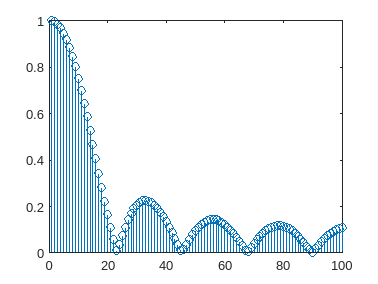

S3 = fft(s3);
H = fft(h);
Y = fft(y);

stem(abs(H(1:length(H)/2)))

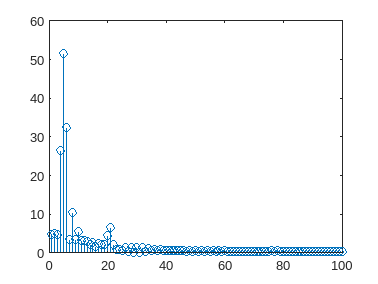

stem(abs(Y(1:length(Y)/2)))

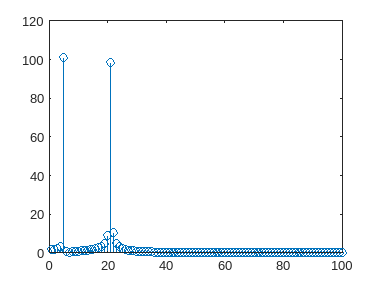

stem(abs(S3(1:length(S3)/2)))


plot(y, 'r')
hold on
plot(s1, 'b')
plot(s2, 'g')
hold off
legend("y(t)", 's1(t)', 's2(t)', 'Location', 'bestoutside')
xlabel('Tempo')
ylabel('Amplitude')
title('Gráfico SINAIS S1, S2 e Y')


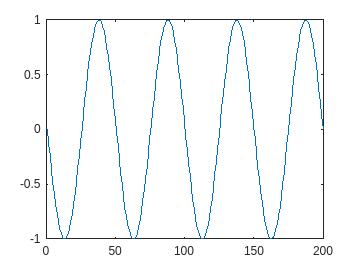

t4 = linspace(0, 8*pi, 200);
s4 = sin(t4) * -1;
plot(s4)

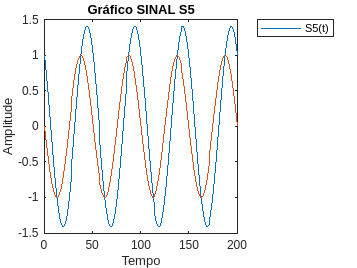


s5 = s1 + s4;
plot(s5)
hold on
plot(s4)
hold off
legend('S5(t)', 'Location', 'bestoutside')
xlabel('Tempo')
ylabel('Amplitude')
title('Gráfico SINAL S5')

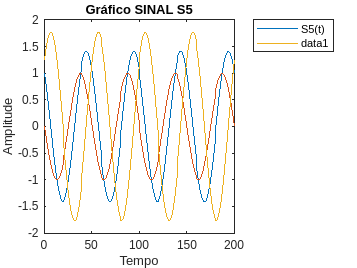

s6 = sqrt(pi) * cos(t4 - (pi/4));
plot(s6)